x=[1 2 3 4; 5 16 7 8; 9 5 12 4]

x =      1     2     3     4
     5    16     7     8
     9     5    12     4


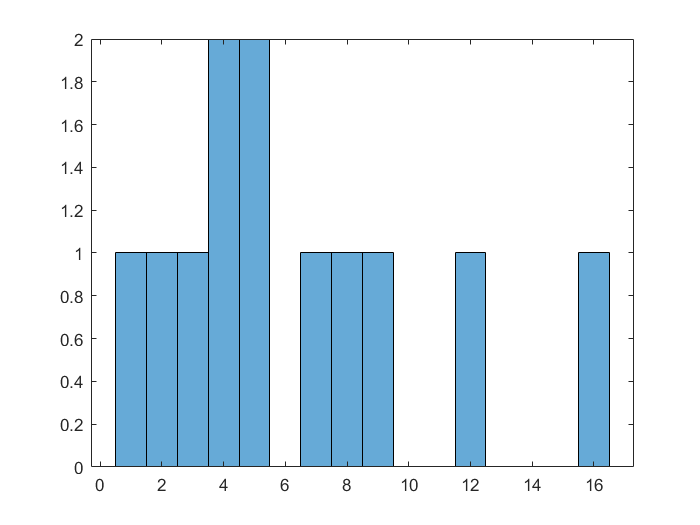


histogram(x);

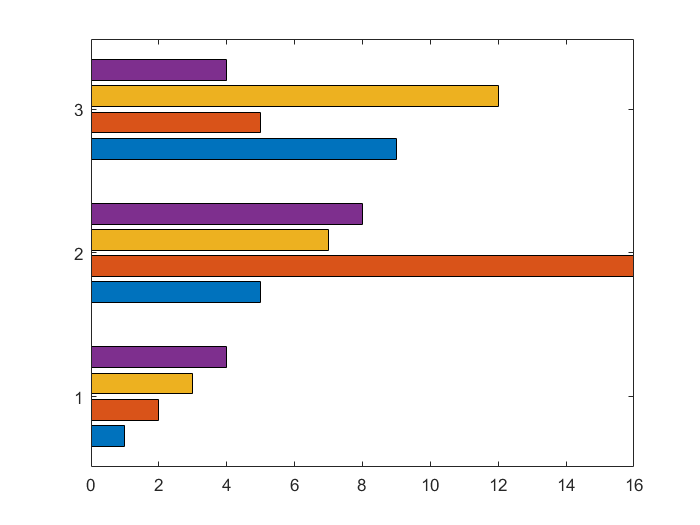

barh(x);

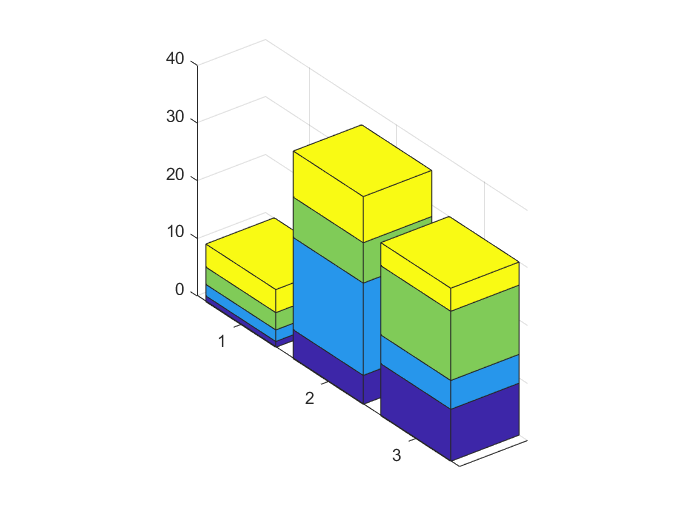

bar3(x,'stack');

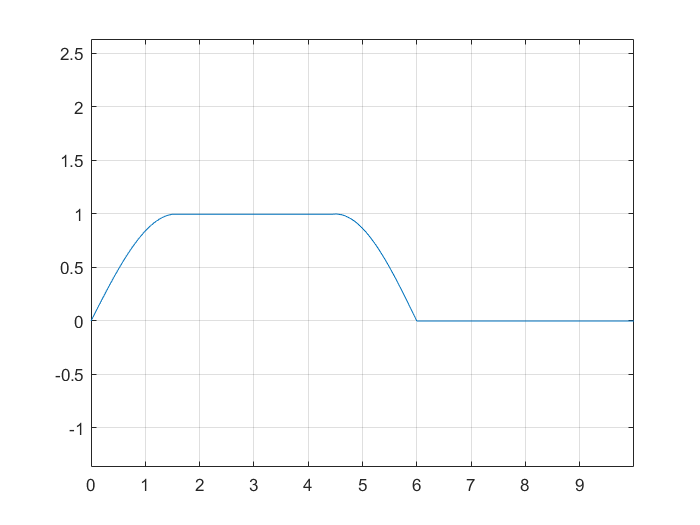


%Camshaft movement graph
th=0:0.01*pi:2*pi;          %THETA
r=linspace(0,length(th));   %RADIUS
t=linspace(0,10,length(th));%TIME

for i=1:length(t)
    if t(i)<1.5
        r(i)=sin(t(i));
    elseif 1.5<=t(i) && t(i)<4.5 
        r(i)=sin(1.5);
    elseif 4.5<=t(i) && t(i)<6
        r(i)=sin((t(i)-3)*pi/3);
    elseif t(i)>=6
        r(i)=0;
    end
end

R=5+r;
plot(t,r);
axis([0 10 -1 3])
grid on;

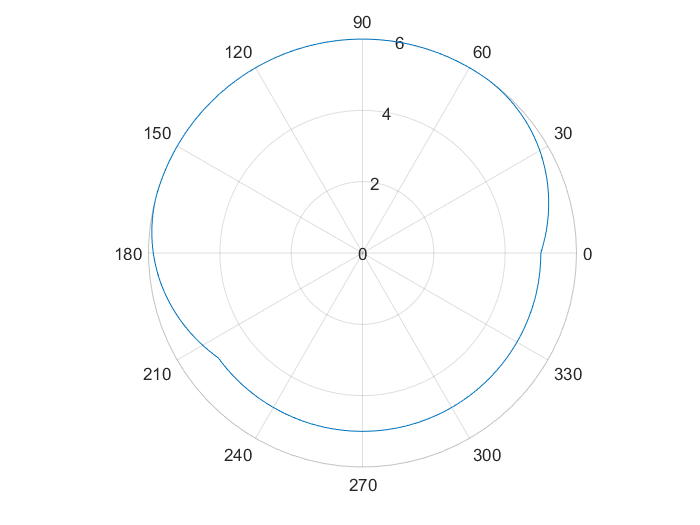

polarplot(th,R);